# **Multiplicative Schwarz **

#                    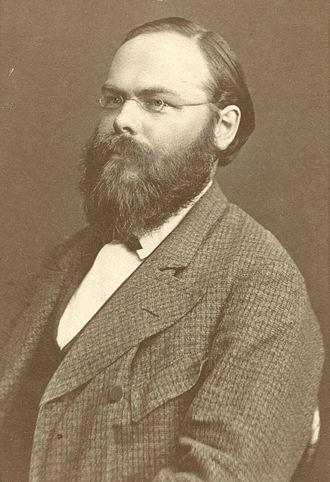 

[Simon Tavener](http://www.math.colostate.edu/~tavener) and Andre Leautaud

Full text can be found at the following [link](https://www.math.colostate.edu/~tavener/andre/DD_multiphysics.pdf)

#### Set path and output level

rehash path
addpath('DD_utilities','Multiplicative_utilities','Inputs')

iprint= 0;

% Create new system, solution strategies and perturbations or read from csv files
sread= true;
input_file= 'DD_param_andre';

% Write system, solution strategies and perturbations to csv files
swrite= false;
output_file= 'DD_param';


#### Establish and solve the forward system, Mx=y

#### Establish subdomains, partitions, number of iterations and random numerical error.  Read and/or save as appropriate

[n,p,K, alpha,nn,nb,ne,index, nnt,nbt,net,indext, M,y,xstore, mpert,wpert]= ...
    linear_system(sread,swrite,input_file,output_file);

Linear_system: Read linear system and solution strategy 



% Note that nnt, nbt, net and idext are required for RAS only. 
% Set alpha= 0
alpha= 0;
fprintf('n= %4i, p= %4i, K= %4i, alpha= %13.4e, mpert= %10.4e \n\n', n, p, K, alpha, mpert)

n=   12, p=    4, K=    6, alpha=    0.0000e+00, mpert= 2.0000e-02 




% Ignore or respect accumulation of error in U iteration
accum= false;

if iprint >= 4
    fprintf('xstore \n')
    disp(xstore)
    disp(y)
end
if iprint >= 6
    fprintf('M \n'); 
    disp(M)
    fprintf('y \n')
    disp(y)
end

#### Iterative strategy

$u^{\{k\}}= u^{\{k-1\}} + Br = u^{\{k-1\}} + B(f-Au^{\{k-1\}}), \quad k=1, \dots, K, $ where $B$ is an approximation to $A^{-1}$

Multiplicative


$$A_i= R_i A R_i^\top \in \mathbb{R}^{m_i \times m_i}, \\
B_i= R_i^\top A_i^{-1} R_i  = R_i^\top ( R_i A R_i^\top)^{-1} R_i  \in \mathbb{R}^{n \times n}, \\
C_i= B_i A   \in \mathbb{R}^{n \times n},  \\
D_i= (I-C_i) \in \mathbb{R}^{n \times n},  \\
f_i= B_i f   \in \mathbb{R}^{n}, \; i=1,\dots,p.
$$


% Construct R, A, B, C, D and f matrices
R= Rmatrices(n,p,nn,index,iprint);
A= Amatrices(M,R,n,p,nn,iprint);
B= Bmatrices(A,R,n,p,nn,iprint);
C= Cmatrices(M,B,n,p,iprint);
D= Dmatrices_multiplicative(C,n,p,iprint);
f= fvector(B,y,n,p,iprint);

#### $K$ iterations computing subdomain contributions independently [D iteration]


$$
u^{\{k+i/p\}} = u^{\{k+(i-1)/p\}} + B_i(f-Au^{\{k+(i-1)/p\}}) =D_i u^{\{k+(i-1)/p\}} + f_i \quad i=1,\dots,p$$


% Perform D iteration
vstore= Diteration_multiplicative(D,f,n,p,K,iprint);
if iprint >= 2
    fprintf('vstore \n')
    disp(vstore')
end

#### $K$ iterations using iteration matrices, $S$ and $T$ which compute the solution in all $p$ domains simultanously [ST iteration]

Let $p=5$ and construct S and T, g and v such that


$$S = \pmatrix{
 I   &  0   &   0   &  0   &   0   \cr
-D_2 &  I   &   0   &  0   &   0   \cr
 0   & -D_3 &   I   &  0   &   0   \cr
 0   &   0  &  -D_4 &  I   &   0   \cr
 0   &   0  &   0   & -D_5 &   I
} \in \mathbb{R}^{np \times np},$$
  
$$T =
\pmatrix{
 0 & 0 & 0 & 0 & -D_1  \cr
 0 & 0 & 0 & 0 &  0    \cr
 0 & 0 & 0 & 0 &  0    \cr
 0 & 0 & 0 & 0 &  0    \cr
 0 & 0 & 0 & 0 &  0
} \in \mathbb{R}^{np \times np}, $$
 
$$g =
\pmatrix{
f_1  \cr
f_2  \cr
f_3  \cr
f_4  \cr
f_5
}
\in \mathbb{R}^{np},$$
 
$$v^{\{k\}} =
\pmatrix{
u^{\{(k-1)+1/5\}}  \cr
u^{\{(k-1)+2/5\}}  \cr
u^{\{(k-1)+3/5\}}  \cr
u^{\{(k-1)+4/5\}}  \cr
u^{\{k\}}
}
\in \mathbb{R}^{np},$$


% Perform ST iteration
S= Smatrix_multiplicative(D,n,p,iprint);
T= Tmatrix_multiplicative(D,n,p,iprint);
g= gvector_multiplicative(f,n,p,iprint);

wstore= STiteration(S,T,g,n,p,K,iprint);
if iprint >= 4
    fprintf('wstore \n')
    disp(wstore')
end

#### $K$ iterations as single matrix solve [U iteration

 $K=6$ iterations of multiplicative Schwarz can be written as the $npK$-dimensional system of equations 

    $Uz=
\pmatrix{
 S & 0 & 0 & 0 & 0 & 0   \cr
 T & S & 0 & 0 & 0 & 0   \cr
 0 & T & S & 0 & 0 & 0   \cr
 0 & 0 & T & S & 0 & 0   \cr
 0 & 0 & 0 & T & S & 0   \cr
 0 & 0 & 0 & 0 & T & S
}

\pmatrix{
v^{\{1\}}  \cr
v^{\{2\}}  \cr
v^{\{3\}}  \cr
v^{\{4\}}  \cr
v^{\{5\}}  \cr
v^{\{6\}}
}
=
\pmatrix{
g  \cr
g  \cr
g  \cr
g  \cr
g  \cr
g
}
=h
$. 

% Perform U iteration
U= Umatrix_multiplicative(S,T,n,p,K,iprint);
h= hvector_multiplicative(g,n,p,K,iprint);

zstore= Uhsolve_multiplicative(U,h,n,p,K,iprint);
if iprint >= 2
    fprintf('zstore \n')
    disp(zstore')
end

#### Compare solutions from all three methods

solution_compare(xstore,vstore(n*p*K-n+1:n*p*K),vstore,wstore,zstore,iprint)

## Add discretization error and compute error estimate

### D iteration with error

psi= ones(n,1);
fprintf('\nPerform D iteration with error \n')

[v_store,va_store,r_store]= Diteration_approx(D,f,n,p,K,mpert,wpert,iprint);
if iprint >= 4
    fprintf('v_store \n')
    disp(v_store')
    fprintf('va_store \n')
    disp(va_store')
    fprintf('r_store \n')
    disp(r_store')    
end

#### *Calculate the discretization error and effectivity ratio*

% Adjoint solve 
[phi_store]= Diteration_adjoint(D,psi,n,p,K,iprint);
if iprint >= 4
    fprintf('phi_store \n')
    disp(phi_store')
end

% Error estimate= (r,\phi)
qoi_discretization_error_estimate= r_store'* phi_store;
if iprint >= 4
    fprintf('norm(r_store) = %13.6e, norm(phi_store)= %13.6e \n', norm(r_store), norm(phi_store))
end

% Compute error and error in QoI directly 
vesoln= v_store(n*p*K+n*(p-1)+1:n*p*(K+1),1);
vsoln= va_store(n*p*K+n*(p-1)+1:n*p*(K+1),1);
verror= vesoln-vsoln;
qoi_discretization_error= psi'*verror;

% Calculate effectivity ratio
effectivity_ratio_disc= qoi_discretization_error_estimate/qoi_discretization_error;

fprintf('QoI_discretization_error          = %13.6e \n', qoi_discretization_error)
fprintf('QoI_discretization_error_estimate = %13.6e \n', qoi_discretization_error_estimate)
fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_disc)

#### *Calculate the total error and effectivity ratio*  

% Adjoint solve
phi= M'\psi;

% Residual
r= y-M*vsoln;

% Error estimate= (r,\phi)
qoi_total_error_estimate= r'*phi;

% Compute error in QoI directly
total_error= xstore-vsoln;
qoi_total_error= psi'*total_error;

% Calculate effectivity ratio
effectivity_ratio_total= qoi_total_error_estimate/qoi_total_error;
fprintf('QoI_total_error                   = %13.6e \n', qoi_total_error)
fprintf('QoI_total_error_estimate          = %13.6e \n', qoi_total_error_estimate)
fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_total)

#### *Calculate the iteration error as the difference between the total error and the discretization error*

qoi_iteration_error= qoi_total_error-qoi_discretization_error;
fprintf('QoI_iteration_error               = %13.6e \n', qoi_iteration_error)


### U iteration with error

fprintf('\nSolving U system with error \n')

if accum
    fprintf('Respecting error accumulation \n')
    [zexact,zapprox,zresid]= Uhsolve_multiplicative_approx_accum(U,D,h,n,p,K,mpert,wpert,iprint);
else
    fprintf('Ignoring error accumulation \n')
    [zexact,zapprox,zresid]= Uhsolve_multiplicative_approx(U,h,n,p,K,mpert,wpert,iprint);
end

if iprint >= 4
    fprintf('zexact \n')
    disp(zexact')
    fprintf('zapprox \n')
    disp(zapprox')
    fprintf('zresid \n')
    disp(zresid')    
end

#### *Calculate the discretization error and effectivity ratio*

% Adjoint data (Adjoint system is of size npK)
psi_npK= zeros(n*p*K,1);
psi_npK(n*p*K-n+1:n*p*K,1)= psi;

% Solve adjoint equation
phi_npK= U'\psi_npK;
if iprint >= 2
    fprintf('Norm of difference between phi_npK and phi_store = %13.6e \n', norm(phi_npK-phi_store))
end

% Compute error estimate
qoi_discretization_error_estimate= phi_npK'*zresid;

% Compute error and error in QoI directly
zsoln= zexact(n*p*K-n+1:n*p*K,1);
zasoln= zapprox(n*p*K-n+1:n*p*K,1);
zerror= zsoln-zasoln;
qoi_discretization_error= psi'*zerror;

% Calculate effectivity ratio
effectivity_ratio_disc= qoi_discretization_error_estimate/qoi_discretization_error;
fprintf('QoI_discretization_error          = %13.6e \n', qoi_discretization_error)
fprintf('QoI_discretization_error_estimate = %13.6e \n', qoi_discretization_error_estimate)
fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_disc)

#### *Calculate the total error and effectivity ratio*

% Residual
r= y-M*zasoln;

% Error estimate= (r,\phi)
qoi_total_error_estimate= r'*phi;

% Compute error in QoI directly
total_error= xstore-zasoln;
qoi_total_error= psi'*total_error;

% Effectivity ratio
effectivity_ratio_total= qoi_total_error_estimate/qoi_total_error;
fprintf('QoI_total_error                   = %13.6e \n', qoi_total_error)
fprintf('QoI_total_error_estimate          = %13.6e \n', qoi_total_error_estimate)
fprintf('Effectivity ratio                 = %13.3f \n', effectivity_ratio_total)

#### *Calculate the iteration error as the difference between the total error and the discretization error*

% Calculate iteration error
qoi_iteration_error= qoi_total_error-qoi_discretization_error;
fprintf('QoI_iteration_error               = %13.6e \n', qoi_iteration_error)